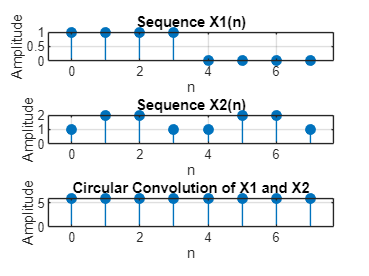



clc;
clear;


X1 = [1, 1, 1, 1, 0, 0, 0, 0]; 
X2 = [1, 2, 2, 1, 1, 2, 2, 1];  

N = max(length(X1), length(X2));


Y = cconv(X1, X2, N);


n = 0:N-1;  

figure;

% Plot the input sequences
subplot(3,1,1);
stem(0:length(X1)-1, X1,'filled');
title('Sequence X1(n)');
xlabel('n');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
stem(0:length(X2)-1, X2, 'filled');
title('Sequence X2(n)');
xlabel('n');
ylabel('Amplitude');
grid on;

% Plot the result of the circular convolution
subplot(3,1,3);
stem(n, Y, 'filled');
title('Circular Convolution of X1 and X2');
xlabel('n');
ylabel('Amplitude');
grid on;